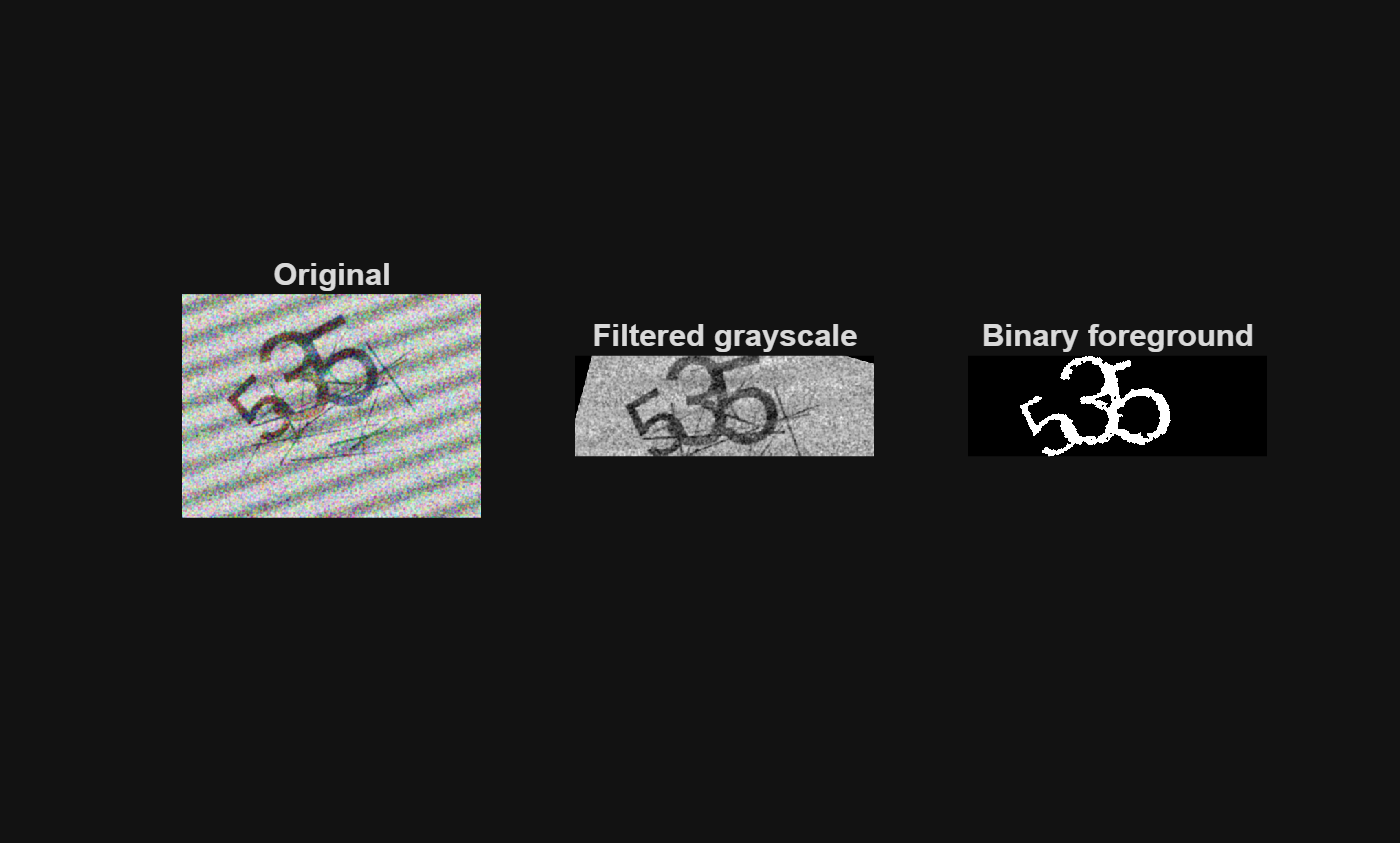

I = imread('C:\Users\Harsh Chitnis\Desktop\IIA_group_13\Train\captcha_0008.png');

[BWfull, Gclean, info] = preprocessCaptcha(I);

figure;
subplot(1,3,1), imshow(I), title('Original')
subplot(1,3,2), imshow(Gclean), title('Filtered grayscale')
subplot(1,3,3), imshow(BWfull), title('Binary foreground')

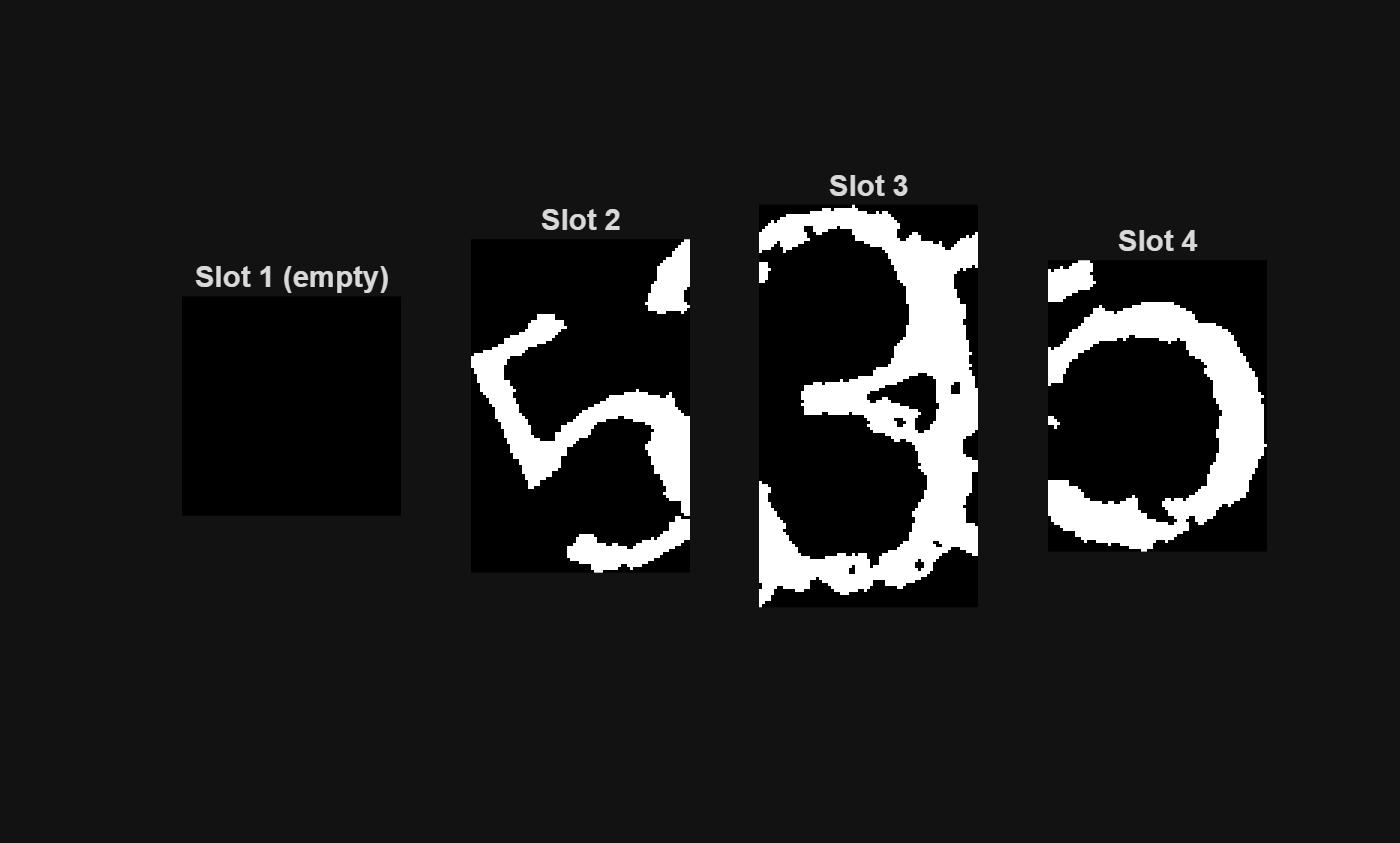


% Run feature extraction
[X4, patches, infoFeat] = Full_FeatureExtraction(I);

% Visualize each digit slot
figure;
for k = 1:4
    subplot(1,4,k);
    if ~isempty(patches{k})
        imshow(patches{k}); title(sprintf('Slot %d', k));
    else
        imshow(zeros(28,28)); title(sprintf('Slot %d (empty)', k));
    end
end

im = imread('Train/captcha_0008.png');
S = myclassifier(im)

S =      0     5     3     5
